% Coded by: Carlo Neil Micael
warning('Copyright Notice: This script is protected by copyright laws. Unauthorized copying, distribution, or modification is prohibited and may result in legal consequences.');

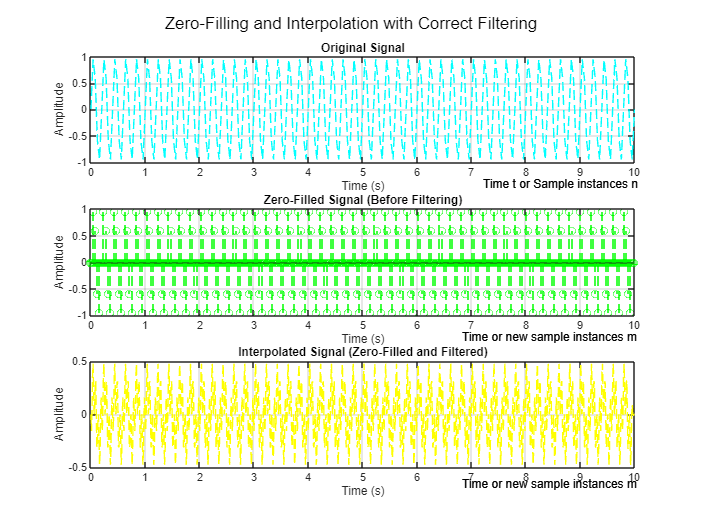

% Start Code Here

% Define original and target sample rates
fs_low = 25;  % Hz Low
fs_high = 50;  % Hz High

% Define signal parameters
freq = 5;  % Hz
time = 10;  % seconds

% Create the original sine wave signal
t = 0:1/fs_low:time;  % Time vector
original_signal = sin(2*pi*freq*t);

% Zero filling (upsample by 4)
upsampling_factor = 4;  % Define a named constant
zero_filled_signal = zeros(1, length(original_signal) * upsampling_factor);
zero_filled_signal(1:upsampling_factor:end) = original_signal;  % Insert the original signal every 2nd sample

% Low-pass filtering (after zero filling)
filter_order = 8;  % Consider increasing the filter order for a sharper cutoff
cutoff_freq = fs_low / 2;  % Nyquist frequency of the original signal

% Design a low-pass filter using the butterworth filter
[b, a] = butter(filter_order, cutoff_freq / (fs_high / 2));  % fs_target / 2 is the Nyquist freq after upsampling

% Apply low-pass filtering (use filtfilt for zero-phase filtering)
interpolated_signal = filtfilt(b, a, zero_filled_signal);  % Zero-phase filtering to avoid delay

% Time vector for upsampled signal (adjust the length to match interpolated_signal)
t_upsampled = linspace(0, time, length(interpolated_signal));  % Adjusted time vector

% Plot the results
figure;
subplot(3,1,1);
plot(t, original_signal, 'c--');
grid on;
annotation('textbox', [0.68, 0.57, 0.1, 0.1], 'String', 'Time t or Sample instances n ', 'EdgeColor', 'none');
annotation('textbox', [0.68, 0.57, 0.1, 0.1], 'String', 'Time t or Sample instances n ', 'EdgeColor', 'none'); % Bold
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
stem(linspace(0, time, length(zero_filled_signal)), zero_filled_signal, 'g--');  % Adjusted stem plot
grid on;
annotation('textbox', [0.65, 0.28, 0.1, 0.1], 'String', 'Time or new sample instances m', 'EdgeColor', 'none');
annotation('textbox', [0.65, 0.28, 0.1, 0.1], 'String', 'Time or new sample instances m', 'EdgeColor', 'none'); % Bold
title('Zero-Filled Signal (Before Filtering)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t_upsampled, interpolated_signal, 'y--');  % Adjusted time vector for the filtered signal
grid on;
annotation('textbox', [0.65, 0.00005, 0.1, 0.1], 'String', 'Time or new sample instances m', 'EdgeColor', 'none');
annotation('textbox', [0.65, 0.00005, 0.1, 0.1], 'String', 'Time or new sample instances m', 'EdgeColor', 'none'); % Bold
title('Interpolated Signal (Zero-Filled and Filtered)');
xlabel('Time (s)');
ylabel('Amplitude');

% Adjust the figure layout
sgtitle('Zero-Filling and Interpolation with Correct Filtering');
set(gcf, 'Position', [100, 100, 800, 600]);

%End Code here